# Simple demo

In this vignette, we'll see how to create a bird and plot it's powercurve function

addpath('data/','functions/')

## Create bird

The `data/bird.csv` file contains some predefined parameters for birds

disp(readtable("bird.csv"))

             commonName                  scientificName           mass     wingSpan    wingAspect        type     
    ____________________________    _________________________    ______    ________    __________    _____________

    {'Mute Swan'               }    {'Cygnus olor'          }       9.6      2.23          9.2       {'waterfowl'}
    {'Greylag Goose'           }    {'Anser anser'          }      3.25      1.64          8.5       {'waterfowl'}
    {'Eider'                   }    {'Somateria mollissima' }      1.63      0.94          8.4       {'waterfowl'}
    {'Red-throated Diver'      }    {'Gavia stellata'       }      1.24      1.11         12.2       {'waterfowl'}
    {'Brent Goose'             }    {'Branta bernicla'      }      1.24      1.15         10.7       {'wa

You can create a bird class easily by using their common or scientific name

bird = Bird("Song Thrush")

bird =   Bird with properties:

                  type: 'passerine'
                  mass: 0.0610
              wingSpan: 0.3400
            wingAspect: 6
              wingArea: 0.0193
       bodyFrontalArea: 0.0023
    basalMetabolicRate: 0.8250


or create your own with `bird = Bird(*mass,*wingSpan,*wingAspect,type)`  where * are required

% bird = Bird(0.215,0.67,0.67^2/0.0652,'passerine')

## Power curve

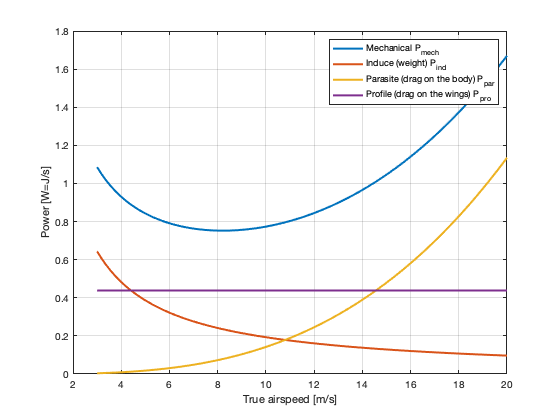

[Pmech,Pind,Ppar,Ppro] = mechanicalPower(bird);
xinterval=[3 20];
figure; hold on; grid on; box on
fplot(Pmech,xinterval,'LineWidth',2)
fplot(Pind,xinterval,'LineWidth',2)
fplot(Ppar,xinterval,'LineWidth',2)
fplot(Ppro,xinterval,'LineWidth',2)
xlabel('True airspeed [m/s]'); ylabel('Power [W=J/s]')
legend('Mechanical P_{mech}','Induce (weight) P_{ind}','Parasite (drag on the body) P_{par}','Profile (drag on the wings) P_{pro}')

## Computing speeds

Define speed as a symbolic variable so that it's easy to solve for equation including derivative.

syms V
P = Pmech;

Compute the derivative of the total power: 

dPdV = diff(P,V);

Minimum power

Vmp = double(solve(dPdV==0,V,'PrincipalValue',true))

Vmp = 8.2066

Minimum range

Vmr = double(solve(dPdV==P/V,V,'PrincipalValue',true, 'MaxDegree', 10,'IgnoreAnalyticConstraints',true))

Vmr = 13.6480

Minimum time

Vmt = double(solve(dPdV==(P+bird.basalMetabolicRate)/V,V,'PrincipalValue',true, 'MaxDegree', 10,'IgnoreAnalyticConstraints',true))

Vmt = 17.3651

Figure

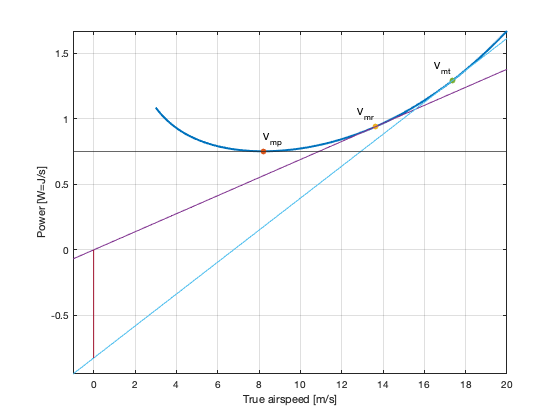

figure; hold on; grid on; box on
% Vmp
fplot(Pmech,xinterval,'LineWidth',2)
scatter(Vmp,double(subs(P,Vmp)),'o','filled')
text(Vmp,0.1+double(subs(P,Vmp)),'V_{mp}')
yline(double(subs(P,Vmp)))
% Vmr
scatter(Vmr,double(subs(P,Vmr)),'o','filled')
text(Vmr-.9,0.1+double(subs(P,Vmr)),'V_{mr}')
fplot(V*double(subs(P,Vmr))/Vmr,[-1 20])
% Vmt
scatter(Vmt,double(subs(P,Vmt)),'o','filled')
text(Vmt-.9,0.1+double(subs(P,Vmt)),'V_{mt}')
fplot(V*double(subs(P,Vmt)+bird.basalMetabolicRate)/Vmt-bird.basalMetabolicRate,[-1 20])
plot([0 0],[0 -bird.basalMetabolicRate])
xlabel('True airspeed [m/s]'); ylabel('Power [W=J/s]');
axis tight;